# HW7

P1

R_Mars = 3397;
mu_Mars = 42828.314258067;
mu = mu_Mars;
a = 6*R_Mars;
e = 0.5;
p = a*(1-e^2);
i = deg2rad(30);
RAAN = deg2rad(45);
AOP = deg2rad(30);
TA1 = deg2rad(150);
dv_xyz = [0.1 0.25 0.35]';
dv = norm(dv_xyz)

dv = 0.4416

C = DCM_xyz2rth(RAAN, TA1+AOP, i)

C =    -0.7071    0.6124    0.3536
   -0.7071   -0.6124   -0.3536
    0.0000   -0.5000    0.8660


dv_rth = C'*dv_xyz

dv_rth =    -0.2475
   -0.2669
    0.2501


norm(dv_rth)

ans = 0.4416


r1 = p/(1+e*cos(TA1))

r1 = 2.6961e+04

v1 = sqrt(2*mu/r1-mu/a)

v1 = 1.0372

gamma1 = acos(sqrt(mu*p)/(r1*v1))

gamma1 = 0.4153

rad2deg(gamma1)

ans = 23.7940


atand(dv_rth(2)/dv_rth(1))

ans = 47.1566


C_h = [cos(-gamma1) sin(-gamma1) 0;
    -sin(-gamma1) cos(-gamma1) 0;
    0 0 1]

C_h =     0.9150   -0.4034         0
    0.4034    0.9150         0
         0         0    1.0000


dv_BVN = C_h*dv_rth

dv_BVN =    -0.1188
   -0.3440
    0.2501


dv_VNB = [dv_BVN(2) dv_BVN(3) dv_BVN(1)]'

dv_VNB =    -0.3440
    0.2501
   -0.1188



v1_rth = v1*[sin(gamma1) cos(gamma1) 0]'

v1_rth =     0.4185
    0.9490
         0



dv_BV = norm(dv_BVN(1:2))

dv_BV = 0.3640

dv_rt = norm(dv_rth(1:2))

dv_rt = 0.3640


phi = atan2(dv_rth(1),dv_rth(2))

phi = -2.3938

rad2deg(phi)

ans = -137.1566

rad2deg(asin(dv_rth(3)/dv))

ans = 34.4933


beta = atan2(dv_rth(3),dv_rt)

beta = 0.6020

rad2deg(beta)

ans = 34.4933


alpha = phi-gamma1

alpha = -2.8091

rad2deg(alpha)

ans = -160.9505


dv_rth(3)/dv

ans = 0.5663

r1_rth = [r1 0 0]';
r2_rth = r1_rth

r2_rth = 	1.0e+04 *

    2.6961
         0
         0



r2_xyz = C*r2_rth

r2_xyz = 	1.0e+04 *

   -1.9064
   -1.9064
    0.0000


r1_xyz = r2_xyz;

v1_xyz = C*v1_rth

v1_xyz =     0.2853
   -0.8771
   -0.4745


v2_xyz = v1_xyz+dv_xyz

v2_xyz =     0.3853
   -0.6271
   -0.1245


r2 = norm(r2_xyz)

r2 = 2.6961e+04

v2 = norm(v2_xyz)

v2 = 0.7464

an = -mu/(2*(v2^2/2-mu/r2))

an = 1.6347e+04

hn_xyz = cross(r2_xyz,v2_xyz)

hn_xyz = 	1.0e+04 *

    0.2374
   -0.2374
    1.9299


hn = norm(hn_xyz)

hn = 1.9589e+04

hn_hat = hn_xyz/hn

hn_hat =     0.1212
   -0.1212
    0.9852


en = sqrt(1-hn^2/(mu*an))

en = 0.6722

pn = hn^2/mu

pn = 8.9599e+03


in = acos(hn_hat(3))

in = 0.1722

rad2deg(in)

ans = 9.8680


omega_n = atan2(0.1212,0.1212)

omega_n = 0.7854

rad2deg(omega_n)

ans = 45


r2_hat = r2_xyz/r2

r2_hat =    -0.7071
   -0.7071
    0.0000


v2_hat = v2_xyz/v2

v2_hat =     0.5162
   -0.8401
   -0.1668


dot(r2_hat,v2_xyz)

ans = 0.1710

theta_an = acos(1/en*(pn/r2-1))

theta_an = 3.0250

rad2deg(theta_an)

ans = 173.3198


In = in;
RAAN_n = omega_n;
AOP_n = pi-theta_an

AOP_n = 0.1166


r3 =[p/(1+e*cos(TA1+pi)) 0 0]';
r3_xyz = DCM_xyz2rth(RAAN,AOP+TA1+pi,i)*r3

r3_xyz = 	1.0e+03 *

    7.5430
    7.5430
   -0.0000


LoN = [r2_xyz r3_xyz];

h_xyz = cross(r1_xyz,v1_xyz);
h_dir = [zeros(3,1) h_xyz];
hn_dir = [zeros(3,1) hn_xyz];

figure
plot_orbit_3d(e,p,RAAN,AOP,i);

plot_orbit_3d(en,pn,RAAN_n,AOP_n,In)

ans = 	1.0e+04 *

    0.3329    0.3061    0.2786    0.2502    0.2209    0.1907    0.1595    0.1272    0.0940    0.0596    0.0240   -0.0128   -0.0510   -0.0906   -0.1316   -0.1742   -0.2185   -0.2645   -0.3125   -0.3624   -0.4144   -0.4686   -0.5251   -0.5842   -0.6457   -0.7100   -0.7770   -0.8468   -0.9196   -0.9952   -1.0736   -1.1548   -1.2384   -1.3241   -1.4114   -1.4996   -1.5877   -1.6744   -1.7582   -1.8371   -1.9087   -1.9703   -2.0190   -2.0514   -2.0644   -2.0550   -2.0210   -1.9608   -1.8744   -1.7628
    0.4197    0.4399    0.4592    0.4774    0.4947    0.5109    0.5262    0.5405    0.5537    0.5658    0.5768    0.5867    0.5953    0.6026    0.6086    0.6130    0.6159    0.6171    0.6163    0.6136    0.6085    0.6011    0.5909    0.5776    0.5611    0.5408    0.5164    0.4874    0.4533    0.4135    0.3674    0.3143    0.2534    0.1840    0.1052    0.0162   -0.0836   -0.1950   -0.3183   -0.4539   -0.6013   -0.7599   -0.9281   -1.1037   -1.2835   -1.4635   -1.6390   -1.8047 

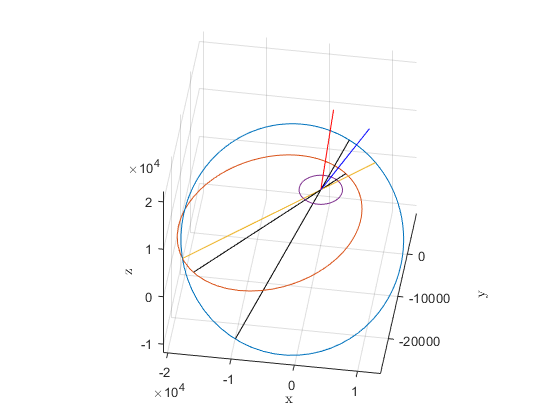


plot3(LoN(1,:),LoN(2,:),LoN(3,:))

plot3(h_dir(1,:),h_dir(2,:),h_dir(3,:),'b')
plot3(hn_dir(1,:),hn_dir(2,:),hn_dir(3,:),'r')

theta = linspace(0,2*pi);
plot(R_Mars*sin(theta),R_Mars*cos(theta))


% items = {'old', 'new', 'Mars Equator'};
% legend(items)

## Problem 2

depJ = 2455779;
arrJ = 2457575;
TOF = arrJ-depJ

TOF = 1796

TOF/365

ans = 4.9205


mu = 132712440017.99;

e1 = 0;
e2 = 0;

aE = 149597898;
aJ = 778279959;

r1 = aE;
r2 = aJ

r2 = 778279959


at = 0.5*(r1+r2)

at = 4.6394e+08

et = 1-r1/at

et = 0.6775

r2/r1

ans = 5.2025

v1 = sqrt(mu/r1)

v1 = 29.7847

vp = sqrt(2*mu/r1-mu/at)

vp = 38.5772

dv1 = vp-v1

dv1 = 8.7925

v2 = sqrt(mu/r2)

v2 = 13.0583

va = sqrt(2*mu/r2-mu/at)

va = 7.4152

dv2 = v2-va

dv2 = 5.6432


dv_total = dv1+dv2

dv_total = 14.4357


period_t = 2*pi*sqrt(at^3/mu)

period_t = 1.7235e+08

TOF = 0.5*period_t

TOF = 8.6176e+07

TOF/(3600*24*365)

ans = 2.7326

eJ = 0.0485359;
r1 = aE;
r2 = aJ*(1-eJ)

r2 = 7.4051e+08

at = 0.5*(r1+r2)

at = 4.4505e+08

v2 = sqrt(2*mu/r2-mu/aJ)

v2 = 13.7083

va = sqrt(2*mu/r2-mu/at)

va = 7.7616

dv2 = v2-va

dv2 = 5.9467

vp = sqrt(2*mu/r1-mu/at)

vp = 38.4195

dv1 = vp-v1

dv1 = 8.6348

dv_total = dv1+dv2

dv_total = 14.5816


2*pi*sqrt(at^3/mu)/2/(3600*24*365)

ans = 2.5675

period_E = 31558205; %sec
period_J = 374479305; %sec

n1 = 2*pi/period_E

n1 = 1.9910e-07

n2 = 2*pi/period_J

n2 = 1.6778e-08

phi = pi-n2*TOF

phi = 1.6957

rad2deg(phi)

ans = 97.1562


ts = 2*pi/(n1-n2)

ts = 3.4462e+07

ts/(3600*24*365)

ans = 1.0928

## Problem 3

R_Earth = 6378.1363;
a = R_Earth+200;
mu = 398600.4415;

r1 = a;
r2 = r1;
v1 = sqrt(mu/r1)

v1 = 7.7843

v2 = sqrt(mu/r2)

v2 = 7.7843


i = deg2rad(57);
dv = sqrt(v1^2+v2^2-2*v1*v2*cos(i))

dv = 7.4287

beta = pi-(pi-i)/2

beta = 2.0682

rad2deg(beta)

ans = 118.5000


dv_vnb = dv*[cos(beta) sin(beta) 0]'

dv_vnb =    -3.5446
    6.5284
         0


r1 = a;
r2 = 55*R_Earth;

ro = r1;
rn = r1;

ra_T = r2;
rp_T = r1;

aT = 0.5*(ra_T+rp_T)

aT = 1.7869e+05

eT = 1-rp_T/aT

eT = 0.9632


v1 = sqrt(mu/r1)

v1 = 7.7843

vp = sqrt(2*mu/r1-mu/aT)

vp = 10.9068

dv1 = vp-v1

dv1 = 3.1226


va = sqrt(2*mu/r2-mu/aT)

va = 0.2045

dv2 = sqrt(2*va^2-2*va^2*cos(i))

dv2 = 0.1952


dv2_vnb = dv2*[cos(beta) sin(beta) 0]'

dv2_vnb =    -0.0931
    0.1715
         0



dv_tot = dv1*2+dv2

dv_tot = 6.4403

TOF = 2*pi*sqrt(aT^3/mu)

TOF = 7.5172e+05


period = 2*pi*sqrt(a^3/mu)/2

period = 2.6548e+03

function C = DCM_xyz2rth(omega, theta, i) %% 3-1-3 Euler Sequence
    C = [cos(omega)*cos(theta)-sin(omega)*cos(i)*sin(theta) -cos(omega)*sin(theta)-sin(omega)*cos(i)*cos(theta) sin(omega)*sin(i);
        sin(omega)*cos(theta)+cos(omega)*cos(i)*sin(theta) -sin(omega)*sin(theta)+cos(omega)*cos(i)*cos(theta) -cos(omega)*sin(i);
        sin(i)*sin(theta) sin(i)*cos(theta) cos(i)];
end